   15.0000
   -2.1568
         0
   -8.0494
         0
  -10.7841

   15.0000
   -2.1568
   -0.0000
   -8.0493
   -0.0000
  -10.7841

   15.0000
   -2.1568
   -0.0000
   -8.0492
   -0.0000
  -10.7840

   15.0000
   -2.1567
   -0.0001
   -8.0490
   -0.0001
  -10.7839

   15.0000
   -2.1567
   -0.0001
   -8.0490
   -0.0001
  -10.7839

   15.0000
   -2.1567
   -0.0001
   -8.0489
   -0.0001
  -10.7838

   15.0000
   -2.1567
   -0.0001
   -8.0489
   -0.0001
  -10.7838

   14.9999
   -2.1566
   -0.0002
   -8.0485
   -0.0003
  -10.7835

   14.9999
   -2.1566
   -0.0003
   -8.0483
   -0.0004
  -10.7834

   14.9999
   -2.1563
   -0.0005
   -8.0472
   -0.0007
  -10.7826

   14.9998
   -2.1562
   -0.0006
   -8.0470
   -0.0008
  -10.7824

   14.9998
   -2.1562
   -0.0006
   -8.0467
   -0.0009
  -10.7823

   14.9998
   -2.1562
   -0.0006
   -8.0467
   -0.0009
  -10.7823

   14.9997
   -2.1557
   -0.0012
   -8.0445
   -0.0016
  -10.7807

   14.9996
   -2.1554
   -0.0015
   -8.0434
   -0.0019
  -10.7

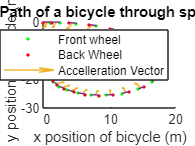

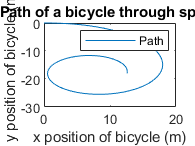

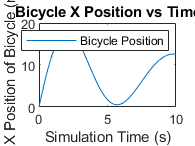

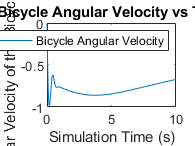

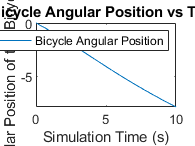

%Team
%Car Turning Simulator
car()

function car
clear all
close all

% Define system parameters
%
mass_car = 1 * 60; % mass in kg
length_car = 1.2; % meters (one leg length)
inertia_car = 1 * 2*(10* (length_car/2)^2); %kg m^2
%15 degree steer angle
steer_angle_r = -1* 15/360 *2*pi; %radians
steer_angle_l = -1* 15/360 *2*pi;
theta_c = 0; % angle between global frame and com of car
theta_trident = 20;
max_force = 1* 500; %newtons


%no starting y velocity, not starting angular velocity
%Z(1) = x, z(2) = vx, Z(3) = y, Z(4) = vy, z(5) = theta_c, z(6) = omega_c
Z_0 = [0,15,0,0,theta_b_0,0]; %15 m/s x velocity start, no other initial conditions

% from 0 to 10 seconds
T_span = [0,10];

% Solve an array of ODE's in terms of every arg, given the initial conditions
[t, zout] = ode45(@car_func, T_span, Z_0);

% Finding values to plot front and back wheel characteristics
step = 10;
t_end = 30 * step;
for i = step:step:t_end
    theta_c = zout(i,5);
    omega_c = zout(i,6);

    x_front_r((i/step)) = zout(i,1) + length_car/2*(cos(theta_c));
    y_front_r(i/step) = zout(i,3) + length_car/2*(sin(theta_c));
    x_back_r(i/step) = zout(i,1) - length_car/2*(cos(theta_c));
    y_back_r(i/step) = zout(i,3) - length_car/2*(sin(theta_c));

    x_front_l(i/step) = zout(i,1) + length_car/2*(cos(theta_c));
    y_front_l(i/step) = zout(i,3) + length_car/2*(sin(theta_c));
    x_back_l(i/step) = zout(i,1) - length_car/2*(cos(theta_c));
    y_back_l(i/step) = zout(i,3) - length_car/2*(sin(theta_c));
    
    
    v_x_front(i/step) = zout(i,2) + length_car/2 * omega_c*(-sin(theta_c));
    v_y_front(i/step) = zout(i,4) + length_car/2 * omega_c*(cos(theta_c));
    %range of atan 2 -pi ->pi
    theta_slip_2 = atan2(v_y_front(i/step)*cos(theta_c + steer_angle) -v_x_front(i/step)*sin(theta_c+steer_angle),...
    v_x_front(i/step)*cos(theta_c + steer_angle) + v_y_front(i/step)*sin(theta_c + steer_angle));
    v_x_back(i/step) = zout(i,2) - length_car/2 * omega_c*(-sin(theta_c));
    v_y_back(i/step) = zout(i,4) - length_car/2 * omega_c*(cos(theta_c));
    %range of atan 2 -pi ->pi
    theta_slip_1 = atan2(v_y_back(i/step)*cos(theta_c) -v_x_back(i/step)*sin(theta_c),...
                v_x_back(i/step)*cos(theta_c) + v_y_back(i/step)*sin(theta_c));

    Force1 = F_eq(theta_slip_1);
    Force2 = F_eq(theta_slip_2);
    ax(i/step) = (- Force1 * sin(theta_c) - Force2 * sin(theta_c + steer_angle))/mass_car;
    ay(i/step) = (Force1 * cos(theta_c) + Force2 * cos(theta_c + steer_angle))/mass_car;
end

% Find xy positions of front & back wheels 
wheels = [x_front;y_front;x_back;y_back]';

% Find xy velocities of front & back wheels 
velocities = [v_x_front; v_y_front; v_x_back;v_y_back]';

% PLOTTING ------------------------------------------------------------%
figure()
hold on
plot(wheels(:,1),wheels(:,2), "g.")
plot(wheels(:,3), wheels(:,4), 'r.')
%quiver(wheels(:,1),wheels(:,2), velocities(:,1),velocities(:,2))
quiver((wheels(:,1) + wheels(:,3))/2,(wheels(:,2) + wheels(:,4))/2, ax(:),ay(:),.5)
%bike frame
%plot([wheels(:,1),wheels(:,3)],[wheels(:,2), wheels(:,4)])
q = quiver(wheels(:,3),wheels(:,4), -wheels(:,3) + wheels(:,1),-wheels(:,4)+wheels(:,2),'off');
q.ShowArrowHead = 'off';
%x vs y
xlabel('x position of bicycle (m)')
ylabel('y position of bicycle (m)')
title('Path of a bicycle through space')
legend('Front wheel','Back Wheel','Accelleration Vector')


hold off
figure()
plot(zout(:,1),zout(:,3));
xlabel('x position of bicycle (m)')
ylabel('y position of bicycle (m)')
title('Path of a bicycle through space')
legend('Path')
%t vs x
figure()
plot(t,zout(:,1))
xlabel('Simulation Time (s)')
ylabel('X Position of Bicycle (m)')
title('Bicycle X Position vs Time')
legend('Bicycle Position')
figure()
% t vs omega
plot(t,zout(:,6))
xlabel('Simulation Time (s)')
ylabel('Angular Velocity of the Bicycle (rad/s)')
title('Bicycle Angular Velocity vs Time')
legend('Bicycle Angular Velocity')
figure()
% t vs omega
plot(t,zout(:,5))
xlabel('Simulation Time (s)')
ylabel('Angular Position of the Bicycle (rad)')
title('Bicycle Angular Position vs Time')
legend('Bicycle Angular Position')
% ------------------------------------------------------------- %


% Creates an array of ODEs for different attributes of the bike (Z_0)
function dzdt = car_func(T,Z)
%Z(1) = x, z(2) = vx, Z(3) = y, Z(4) = vy, z(5) = theta_c, z(6) = omega_c
%all in relation to COM

theta_c = Z(5);_
omega_c = Z(6);

%in terms of i and j (global frame) %ASK LUKE
v_x_front_r = Z(2) + length_car/2 * omega_c*(-sin(theta_c-theta_trident));
v_y_front_r = Z(4) + length_car/2 * omega_c*(cos(theta_c-theta_trident));
v_x_front_l = Z(2) + length_car/2 * omega_c*(-sin(theta_c+theta_trident));
v_y_front_l = Z(4) + length_car/2 * omega_c*(cos(theta_c+theta_trident));

v_x_back_r = Z(2) - length_car/2 * omega_c*(-sin(theta_c-pi+theta_trident));
v_y_back_r = Z(4) - length_car/2 * omega_c*(cos(theta_c-pi+theta_trident));
v_x_back_l = Z(2) - length_car/2 * omega_c*(-sin(theta_c-pi-theta_trident));
v_y_back_l = Z(4) - length_car/2 * omega_c*(cos(theta_c-pi-theta_trident));

%range of atan 2 -pi ->pi
% ask luke why you add theta_c and steer_angle when it should be subtract
theta_slip_r = atan2(v_y_front*cos(theta_c + steer_angle) -v_x_front*sin(theta_c+steer_angle),...
                v_x_front*cos(theta_c + steer_angle) + v_y_front*sin(theta_c + steer_angle));


%range of atan 2 -pi ->pi
theta_slip_1 = atan2(v_y_back*cos(theta_c) -v_x_back*sin(theta_c),...
                v_x_back*cos(theta_c) + v_y_back*sin(theta_c));

Force1 = F_eq(theta_slip_1);
Force2 = F_eq(theta_slip_2);

ax = (- Force1 * sin(theta_c) - Force2 * sin(theta_c + steer_angle))/mass_car;
ay = (Force1 * cos(theta_c) + Force2 * cos(theta_c + steer_angle))/mass_car;

alpha = (-length_car/2 * Force1 + length_car/2 *Force2 *sin(steer_angle + pi))/inertia_car;
            
            
dz1dt = Z(2); % X pos ODE
dz2dt = ax; % X vel ODE
dz3dt = Z(4); % Y pos ODE
dz4dt = ay; % Y vel ODE
dz5dt = Z(6); % Ang ODE
dz6dt = alpha; % Angle vel ODE
%
dzdt = [dz1dt;dz2dt;dz3dt;dz4dt;dz5dt;dz6dt];
disp(dzdt)
%
end

%function for finding the force output as a function of slip angle
    function outp = F_eq(angle)
        thresh = 15/360 *2*pi;
        
        
        if angle < -thresh
           outp =  max_force;
        elseif angle >= -thresh
           outp =  -(angle*max_force/thresh);
        end
        if angle > thresh
           outp = -max_force;
        end
        
    end

% e_range = linspace(-pi,pi,60);
% F_eq_list = [];

% %test if the function works
% for i = 1:60
%    F_eq_list(i) = F_eq(e_range(i));
% end
% %plot(e_range,F_eq_list)

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

end







